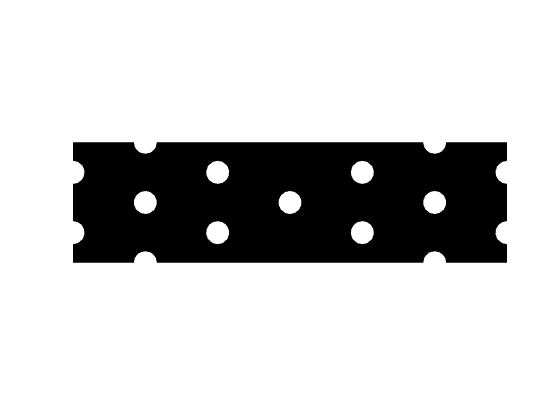

nelx=90;nely=25;volfrac=0.45;
%% LEVEL SET FUNCTION INITIALIZATION
r = nely*0.1;%RADIUS OF INITIAL HOLES
hX = nelx*[repmat([1/6,5/6],1,3),repmat([0,1/3,2/3,1],1,2),1/2];
hY = nely*[kron([0,1/2,1],ones(1,2)),kron([1/4,3/4],ones(1,4)),1/2];
[X,Y] = meshgrid(0:1:nelx,0:1:nely);
dX = bsxfun(@minus,repmat(X,[1,1,numel(hX)]),reshape(hX,1,1,numel(hX)));
dY = bsxfun(@minus,repmat(Y,[1,1,numel(hY)]),reshape(hY,1,1,numel(hY)));
Phi = max(-3,min(3,min(sqrt(dX.^2+dY.^2)-r,[],3)));
pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
gradPhi = sqrt((pGpX).^2+(pGpY).^2);
figure(1); contourf(Phi,[0,0]);
colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;

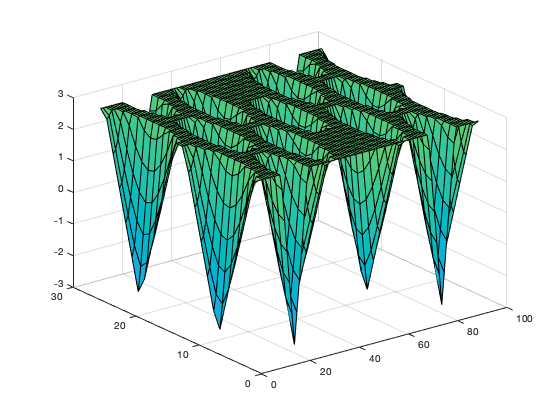

figure(2); surf(Phi); caxis([-12,12]);

No.1, Obj:859718.358306, Vol:0.903365


No.2, Obj:776344.413629, Vol:0.915705


No.3, Obj:739934.439980, Vol:0.914890


No.4, Obj:735060.422480, Vol:0.900428


No.5, Obj:737178.379947, Vol:0.876092


No.6, Obj:740208.371228, Vol:0.841852


No.7, Obj:737728.221752, Vol:0.821468


No.8, Obj:732968.589420, Vol:0.815446


No.9, Obj:772130.499252, Vol:0.776123


No.10, Obj:737236.757340, Vol:0.808911


No.11, Obj:780705.416809, Vol:0.739761


No.12, Obj:740259.605797, Vol:0.787785


No.13, Obj:778269.652455, Vol:0.724376


No.14, Obj:760682.515309, Vol:0.745727


No.15, Obj:798737.561268, Vol:0.698931


No.16, Obj:779653.068574, Vol:0.714878


No.17, Obj:822018.258022, Vol:0.665560


No.18, Obj:798381.320572, Vol:0.686071


No.19, Obj:828018.161258, Vol:0.647851


No.20, Obj:825037.837532, Vol:0.647575


No.21, Obj:841874.631134, Vol:0.627479


No.22, Obj:851800.598063, Vol:0.615383


No.23, Obj:865350.841110, Vol:0.599871


No.24, Obj:876879.704280, Vol:0.587263


No.25, Obj:892316.180354, Vol:0.572017


No.26, Obj:905551.887611, Vol:0.559331


No.27, Obj:921326.012168, Vol:0.545568


No.28, Obj:935931.990463, Vol:0.533112


No.29, Obj:952511.600056, Vol:0.519716


No.30, Obj:969238.019499, Vol:0.506902


No.31, Obj:985239.883284, Vol:0.495321


No.32, Obj:997880.461812, Vol:0.485851


No.33, Obj:1004328.126937, Vol:0.480786


No.34, Obj:1010261.476685, Vol:0.476608


No.35, Obj:1014182.523679, Vol:0.473377


No.36, Obj:1018610.847883, Vol:0.470365


No.37, Obj:1020410.518020, Vol:0.468948


No.38, Obj:1024275.064817, Vol:0.466473


No.39, Obj:1024668.914737, Vol:0.465987


No.40, Obj:1026342.782054, Vol:0.464877


No.41, Obj:1027847.243823, Vol:0.463680


No.42, Obj:1028972.814201, Vol:0.462974


No.43, Obj:1028946.355769, Vol:0.462617


No.44, Obj:1030675.326207, Vol:0.461777


No.45, Obj:1029333.721885, Vol:0.462134


No.46, Obj:1031842.088503, Vol:0.461039


No.47, Obj:1030012.032067, Vol:0.461499


No.48, Obj:1032723.810365, Vol:0.460275


No.49, Obj:1032589.143971, Vol:0.459880


No.50, Obj:1035756.596150, Vol:0.458437


No.51, Obj:1034562.610667, Vol:0.458602


No.52, Obj:1035676.829573, Vol:0.458237


No.53, Obj:1034103.391922, Vol:0.458842


No.54, Obj:1035546.380348, Vol:0.458171


No.55, Obj:1034727.493598, Vol:0.458449


No.56, Obj:1036926.935860, Vol:0.457381


No.57, Obj:1038210.939012, Vol:0.456441


No.58, Obj:1042659.922681, Vol:0.453998


No.59, Obj:1044795.238735, Vol:0.452620


No.60, Obj:1048258.228023, Vol:0.450763


No.61, Obj:1051161.700159, Vol:0.449080


No.62, Obj:1053913.577836, Vol:0.447486


No.63, Obj:1055330.506411, Vol:0.446629


No.64, Obj:1056815.221867, Vol:0.445787


No.65, Obj:1056860.171444, Vol:0.445761


No.66, Obj:1057867.839551, Vol:0.445237


No.67, Obj:1058931.861817, Vol:0.444561


No.68, Obj:1059556.328924, Vol:0.444235


No.69, Obj:1057520.906931, Vol:0.445295


No.70, Obj:1055049.520899, Vol:0.446716


No.71, Obj:1053190.719189, Vol:0.447859


No.72, Obj:1052230.383786, Vol:0.448433


No.73, Obj:1052199.562560, Vol:0.448504


No.74, Obj:1052094.658517, Vol:0.448617


No.75, Obj:1051001.013753, Vol:0.449262


No.76, Obj:1049552.778307, Vol:0.450108


No.77, Obj:1049388.917602, Vol:0.450284


No.78, Obj:1049344.512866, Vol:0.450391


No.79, Obj:1049518.037810, Vol:0.450393


No.80, Obj:1049259.025783, Vol:0.450602


No.81, Obj:1048638.772650, Vol:0.451132


No.82, Obj:1049908.749838, Vol:0.450741


No.83, Obj:1048573.880604, Vol:0.451701


No.84, Obj:1051766.795086, Vol:0.452713


No.85, Obj:1052439.115368, Vol:0.455143


No.86, Obj:1048552.195697, Vol:0.454208


No.87, Obj:1052233.677804, Vol:0.455180


No.88, Obj:1064957.046325, Vol:0.454208


No.89, Obj:1066331.304805, Vol:0.454853


No.90, Obj:1060948.903591, Vol:0.456468


No.91, Obj:1057041.964365, Vol:0.456873


No.92, Obj:1057412.139634, Vol:0.456302


No.93, Obj:1055082.086041, Vol:0.456087


No.94, Obj:1055787.499323, Vol:0.455178


No.95, Obj:1058205.881669, Vol:0.453353


No.96, Obj:1061682.228783, Vol:0.451205


No.97, Obj:1064636.115905, Vol:0.449187


No.98, Obj:1064903.089265, Vol:0.448927


No.99, Obj:1064372.023177, Vol:0.449115


No.100, Obj:1063775.029185, Vol:0.449363


No.101, Obj:1063409.373714, Vol:0.449498


No.102, Obj:1062537.612674, Vol:0.449921


No.103, Obj:1061620.117098, Vol:0.450354


No.104, Obj:1061693.035269, Vol:0.450262


No.105, Obj:1061997.134891, Vol:0.450018


No.106, Obj:1061212.544489, Vol:0.450419


No.107, Obj:1060165.379766, Vol:0.450979


No.108, Obj:1058881.535220, Vol:0.451662


No.109, Obj:1057976.389373, Vol:0.452160


No.110, Obj:1057753.921529, Vol:0.452255


No.111, Obj:1058053.059091, Vol:0.452063


No.112, Obj:1059025.985574, Vol:0.451495


No.113, Obj:1060064.698490, Vol:0.450856


No.114, Obj:1060773.344261, Vol:0.450447


No.115, Obj:1061390.178013, Vol:0.450076


No.116, Obj:1061916.637746, Vol:0.449758


No.117, Obj:1062545.542718, Vol:0.449385


No.118, Obj:1063235.610118, Vol:0.448974


No.119, Obj:1064117.270498, Vol:0.448445


No.120, Obj:1063966.238051, Vol:0.448510


No.121, Obj:1063697.459500, Vol:0.448641


No.122, Obj:1062165.218659, Vol:0.449562


No.123, Obj:1060114.653398, Vol:0.450697


No.124, Obj:1059841.220268, Vol:0.450876


No.125, Obj:1059690.989117, Vol:0.450917


No.126, Obj:1059985.166583, Vol:0.450767


No.127, Obj:1061216.489456, Vol:0.450064


No.128, Obj:1061747.497558, Vol:0.449762


No.129, Obj:1061250.280243, Vol:0.450038


No.130, Obj:1059281.398631, Vol:0.451140


No.131, Obj:1058121.994258, Vol:0.451783


No.132, Obj:1057591.060201, Vol:0.452110


No.133, Obj:1058212.268203, Vol:0.451743


No.134, Obj:1058669.832132, Vol:0.451481


No.135, Obj:1059289.187518, Vol:0.451128


No.136, Obj:1060892.885092, Vol:0.450217


No.137, Obj:1062214.631740, Vol:0.449463


No.138, Obj:1063013.324139, Vol:0.449014


No.139, Obj:1063327.964751, Vol:0.448836


No.140, Obj:1063291.966696, Vol:0.448814


No.141, Obj:1063199.258087, Vol:0.448845


No.142, Obj:1063299.720932, Vol:0.448770


No.143, Obj:1062353.127371, Vol:0.449310


No.144, Obj:1061796.823179, Vol:0.449612


No.145, Obj:1060890.649525, Vol:0.450116


No.146, Obj:1060379.464360, Vol:0.450389


No.147, Obj:1059806.534208, Vol:0.450699


No.148, Obj:1059498.270074, Vol:0.450866


No.149, Obj:1060248.999416, Vol:0.450417


No.150, Obj:1060996.947329, Vol:0.449981


No.151, Obj:1061240.916875, Vol:0.449816


No.152, Obj:1061283.615520, Vol:0.449784


No.153, Obj:1060996.367512, Vol:0.449937


No.154, Obj:1060228.659722, Vol:0.450376


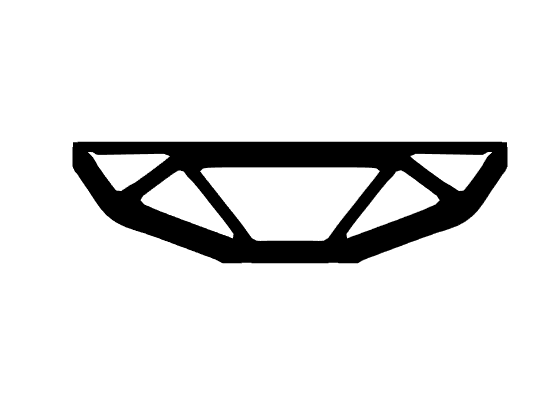

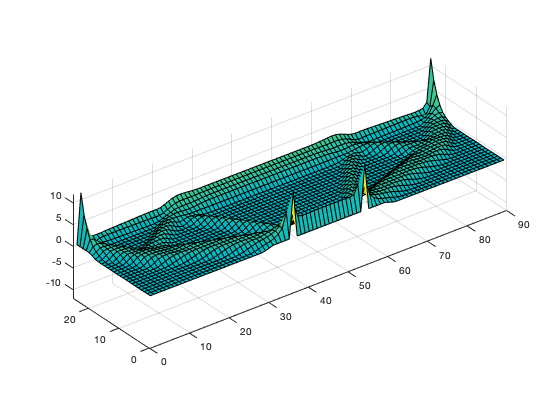

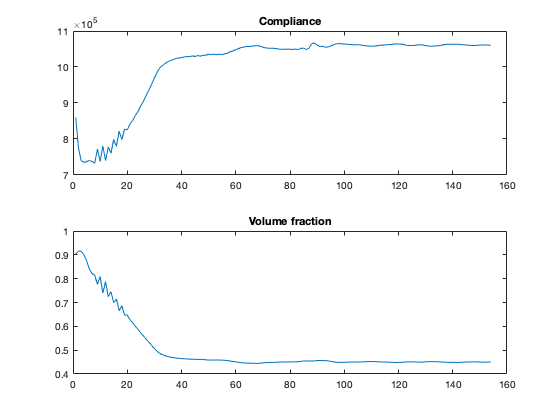

%% RADIAL BASIS FUNCTION INITIALIZATION
nNode = (nely+1)*(nelx+1);
Boundary = setdiff(unique([1:1:nely+1, nNode-nely:1:nNode, ... 
    nely+1:nely+1:nNode, 1:nely+1:nNode-nely]), ...
    [(nely+1),nNode,0.4*nelx*(nely+1)+1,0.6*nelx*(nely+1)+1]);
Phi(Boundary)=-1e-9;
Alpha = Phi(:);
Phi = reshape(Alpha,nely+1,nelx+1);
%% FINITE ELEMENT ANALYSIS PREPARATION
E0 = 1; Emin = 1e-9; nu = 0.3; %MATERIAL PROPERTIES
A11 = [12 3 -6 -3; 3 12 3 0; -6 3 12 -3; -3 0 -3 12];
A12 = [-6 -3 0 3; -3 -6 -3 -6; 0 -3 -6 3; 3 -6 3 -6];
B11 = [-4 3 -2 9; 3 -4 -9 4; -2 -9 -4 -3; 9 4 -3 -4];
B12 = [ 2 -3 4 -9; -3 2 9 -2; 4 9 2 3; -9 -2 3 2];
KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
eleN1 = repmat((1:nely)',1,nelx)+kron(0:nelx-1,(nely+1)*ones(nely,1));
eleNode = repmat(eleN1(:),1,4)+repmat([0,nely+[1,2],1],nelx*nely,1);
edofMat = kron(eleNode,[2,2])+repmat([-1,0],nelx*nely,4);
iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
%% BOUNDARY CONDITION DEFINITION
F = sparse([2*(nely+1),2*nNode],[1,1],[-100,-100],2*nNode,1);
fixeddofs = [2*0.4*nelx*(nely+1)+2,2*0.6*nelx*(nely+1)+2];
freedofs = setdiff(1:2*nNode,fixeddofs);
U = zeros(2*nNode,1);
%% ITERATION OPTIMIZATION
nLoop = 500; nRelax = 30;
dt = 0.2; delta = 20; mu = 20; gamma = 0.05;
comp = zeros(nLoop,1); vol = zeros(nLoop,1);
for iT = 1:nLoop
    %% FINITE ELEMENT ANALYSIS
        [s,t] = meshgrid(-1:0.1:1,-1:0.1:1);
    tmpPhi = (1-s(:)).*(1-t(:))/4*Phi(eleNode(:,1))'+(1+s(:)).*(1-t(:))/4*...
        Phi(eleNode(:,2))'+(1+s(:)).*(1+t(:))/4*Phi(eleNode(:,3))'+...
        (1-s(:)).*(1+t(:))/4*Phi(eleNode(:,4))';
    eleVol = sum(tmpPhi>=0,1)'/numel(s);
    vol(iT) = sum(eleVol)/(nelx*nely);
    sK = reshape(KE(:)*(Emin+eleVol'*(E0-Emin)),64*nelx*nely,1);
    K = sparse(iK,jK,sK); K = (K+K')/2;
    U(freedofs,1) = K(freedofs,freedofs)\F(freedofs,1);
    eleComp = sum((U(edofMat)*KE).*U(edofMat),2).*(Emin+eleVol*(E0-Emin));
    comp(iT) = sum(eleComp);
    %% DISPLAY RESULTS
    fprintf('No.%i, Obj:%f, Vol:%f\n',[iT,comp(iT),vol(iT)]);
    figure(3); contourf(Phi,[0,0]);
    colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;
    %saveas(gcf,sprintf('Optim_pictures/%i.png', iT));
    figure(4); surf(Phi); caxis([-12,12]);
    axis equal; axis([0,nelx,0,nely,-12,12]); view(3);
    figure(5);  subplot(2,1,1); plot(comp(1:iT),'-'); title('Compliance');
                subplot(2,1,2); plot(vol(1:iT),'-'); title('Volume fraction');
    %% CONVERGENCE CHECK
    if iT>nRelax && abs(vol(iT)-volfrac)/volfrac<1e-3 && ...
        all(abs(comp(iT)-comp(iT-9:iT-1))/comp(iT)<1e-3)
        break;
    end
    %% LAGRANGE MULTIPLIER
    if iT<=nRelax
        lag = mu*(vol(iT)-vol(1)+(vol(1)-volfrac)*iT/nRelax);
    else
        lag = lag+gamma*(vol(iT)-volfrac);
        gamma = min(gamma+0.05,5);
    end
    %% LEVEL SET FUNCTION EVOLUTION
    pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
    pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
    gradPhi = sqrt((pGpX).^2+(pGpY).^2);
    indexDelta = (abs(Phi(:))<=delta);
    DeltaPhi = zeros(size(Phi));
    DeltaPhi(indexDelta) = 0.75/delta*(1-Phi(indexDelta).^2/delta^2);
    eleComp = reshape(eleComp,nely,nelx);
    eleCompLR = [eleComp(:,1),eleComp]+[eleComp,eleComp(:,end)];
    nodeComp = ([eleCompLR;eleCompLR(end,:)]+[eleCompLR(1,:);eleCompLR])/4;
    B = (nodeComp(:)/median(nodeComp(:))-lag).*DeltaPhi(:)*delta/0.75;
    Alpha = Alpha+dt*B;
    Alpha = Alpha/mean(gradPhi(unique(eleNode((eleVol<1 & eleVol>0),:))));%broke the program when the body is solid, but prevent oscilations
    Phi = reshape(Alpha,nely+1,nelx+1);
    Phi(Boundary)=min(Phi(Boundary),-1e-9);
end